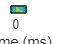




% specify baseline periods for dB-conversion


baseline_windows = [ -1000 -500];


               
% convert baseline time into indices
baseidx = reshape( dsearchn(EEG.times',baseline_windows(:)), [],2);

%% setup wavelet parameters

% frequency parameters
min_freq =  0.5;
max_freq = 125;
num_frex = 125;
frex = linspace(min_freq,max_freq,num_frex);

% which channel to plot
channel2use = 'af3';

% other wavelet parameters
range_cycles = [ 4 10 ];

% notice: defining cycles as a vector for all frequencies
s = logspace(log10(range_cycles(1)),log10(range_cycles(end)),num_frex) ./ (2*pi*frex);
wavtime = -2:1/EEG.srate:2;
half_wave = (length(wavtime)-1)/2;


% FFT parameters
nWave = length(wavtime);
nData = EEG.pnts * EEG.trials;
nConv = nWave + nData - 1;


% now compute the FFT of all trials concatenated
alldata = reshape( EEG.data(strcmpi(channel2use,{EEG.chanlocs.labels}),:,:) ,1,[]);
dataX   = fft( alldata ,nConv );


% initialize output time-frequency data
tf = zeros(size(baseidx,1),length(frex),EEG.pnts);

%% now perform convolution

% loop over frequencies
for fi=1:length(frex)
    
    % create wavelet and get its FFT
    wavelet  = exp(2*1i*pi*frex(fi).*wavtime) .* exp(-wavtime.^2./(2*s(fi)^2));
    waveletX = fft(wavelet,nConv);
    waveletX = waveletX ./ max(waveletX);
    
    % now run convolution in one step
    as = ifft(waveletX .* dataX);
    as = as(half_wave+1:end-half_wave);
    
    % and reshape back to time X trials
    as = reshape( as, EEG.pnts, EEG.trials );
    
    % compute power and average over trials
    tf(4,fi,:) = mean( abs(as).^2 ,2);
end

%% db normalization and plot results

% define color limits
clim = [-3 3];



for basei=1%:size(tf,1)
    
    activity = tf(4,:,:);
    if size(tf,1)==1
        baseline = mean( tf(4,:,baseidx(1):baseidx(2)) ,3);
    else
        baseline = mean( tf(4,:,baseidx(basei,1):baseidx(basei,2)) ,3);
    end

    
    % decibel
    tf(basei,:,:) = 10*log10( bsxfun(@rdivide, activity, baseline) );
end


% plot results
figure(15), clf
for basei=1:size(baseline_windows,1)
    
    subplot(1,1,basei)
    
    contourf(EEG.times,frex,squeeze(tf(basei,:,:)),120,'linecolor','none')
    set(gca,'clim',clim,'ydir','normal')
    title([ 'DB baseline of ' num2str(baseline_windows(basei,1)) ' to ' num2str(baseline_windows(basei,2)) ' ms' ])
end

xlabel('Time (ms)'), ylabel('Frequency (Hz)')